# Invertibility, minimum-phase and allpass

## Allpass systems

The definition of allpass is that the magnitude of its frequency response is constant $G$ (usually $G=1$) for all frequencies. 

        

We can say that:

- an allpass system treats all frequencies identically with respect to gain

- an allpass system preserves the power or energy of their input signals  

The system function of an allpass system has the poles and zeros occur in conjugate reciprocal pairs

        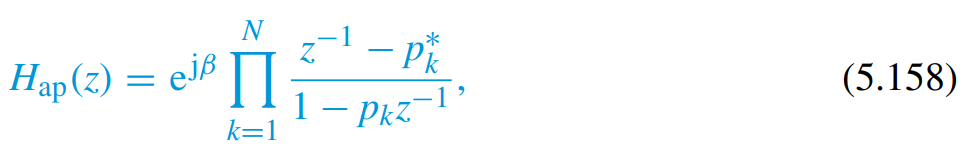

where $\beta$ is constant that is usually set to $\beta =0$.

So if we have a pole $p_k =re^{j\phi }$ then the zero is located at $\frac{1}{p_k^* }=\frac{1}{r}e^{j\phi }$

        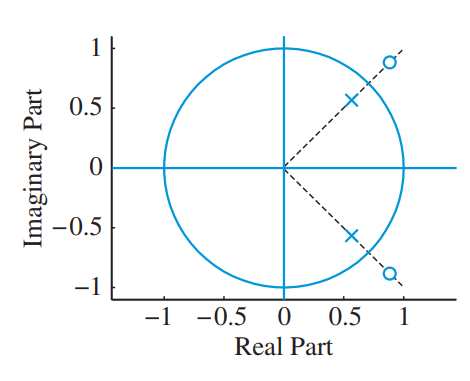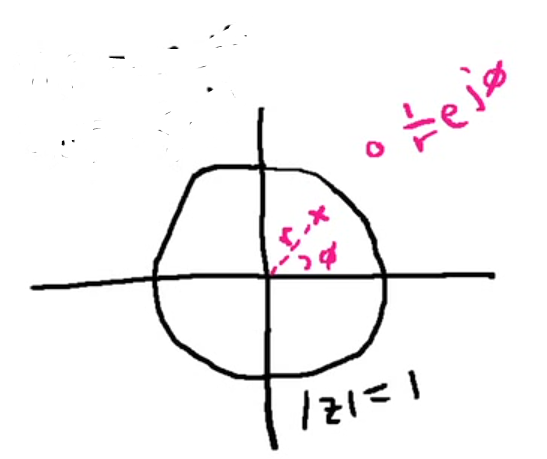

A second-order allpass filter is given by:

        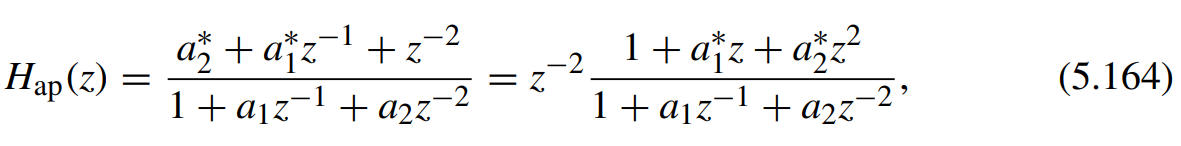

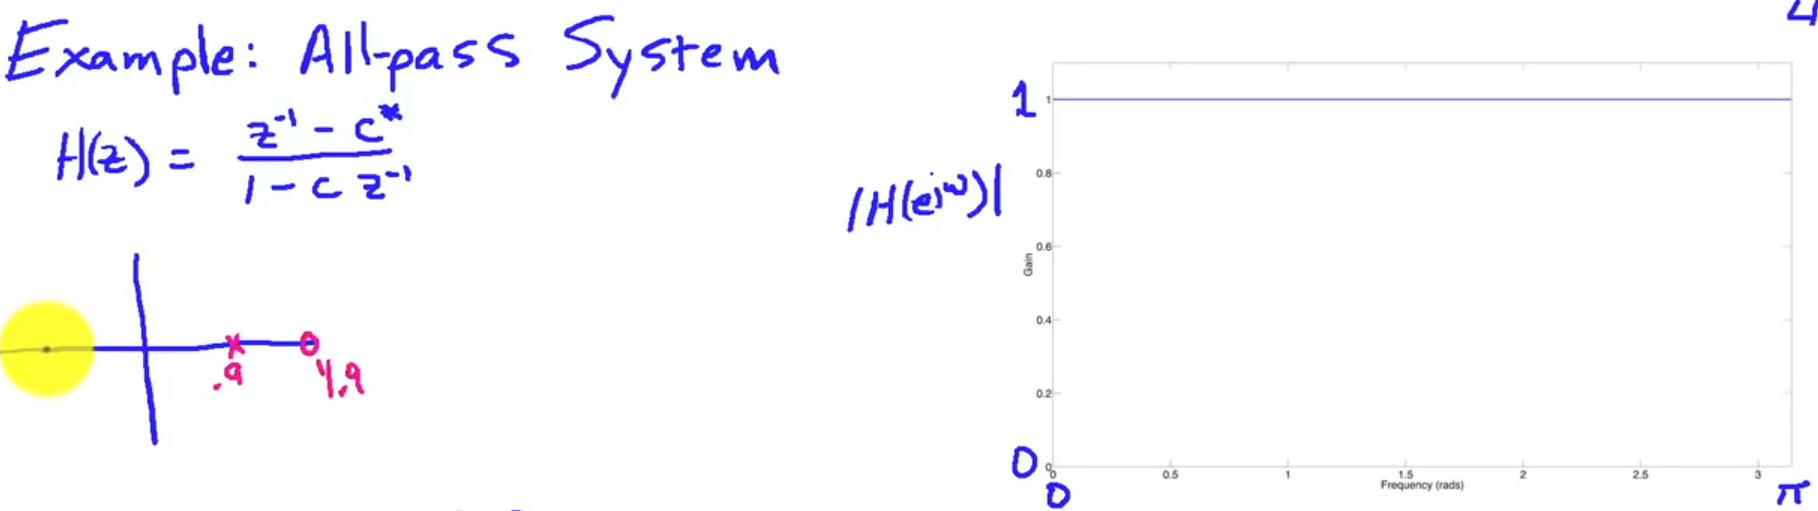

Although the magnitude response is the same, the phase response changes depending on the pole.

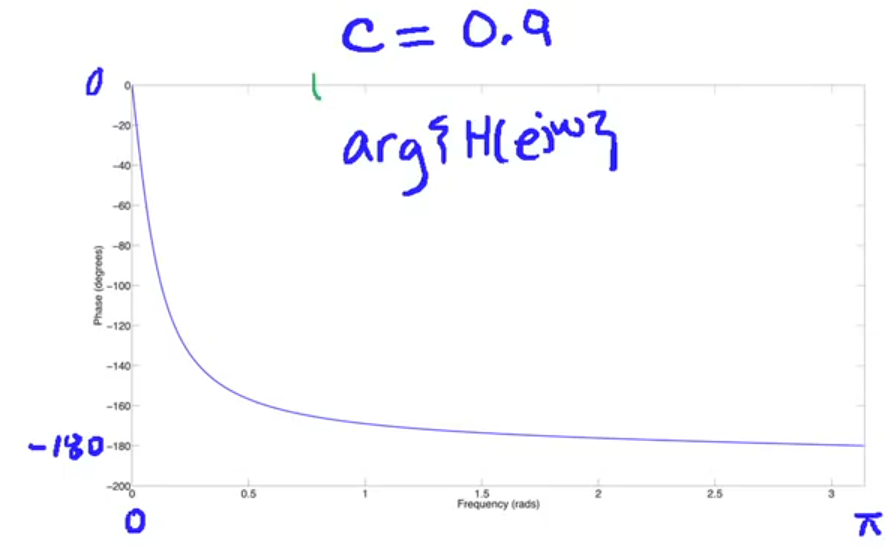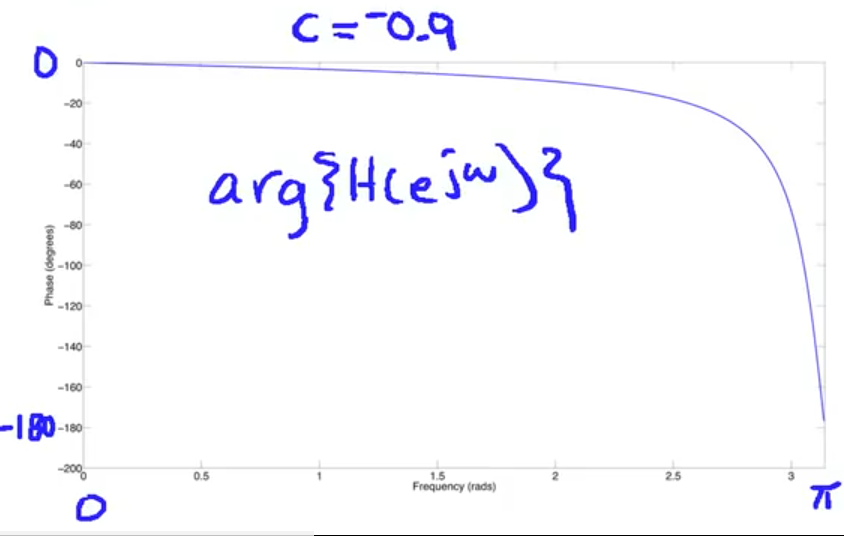

## Minimum-phase systems

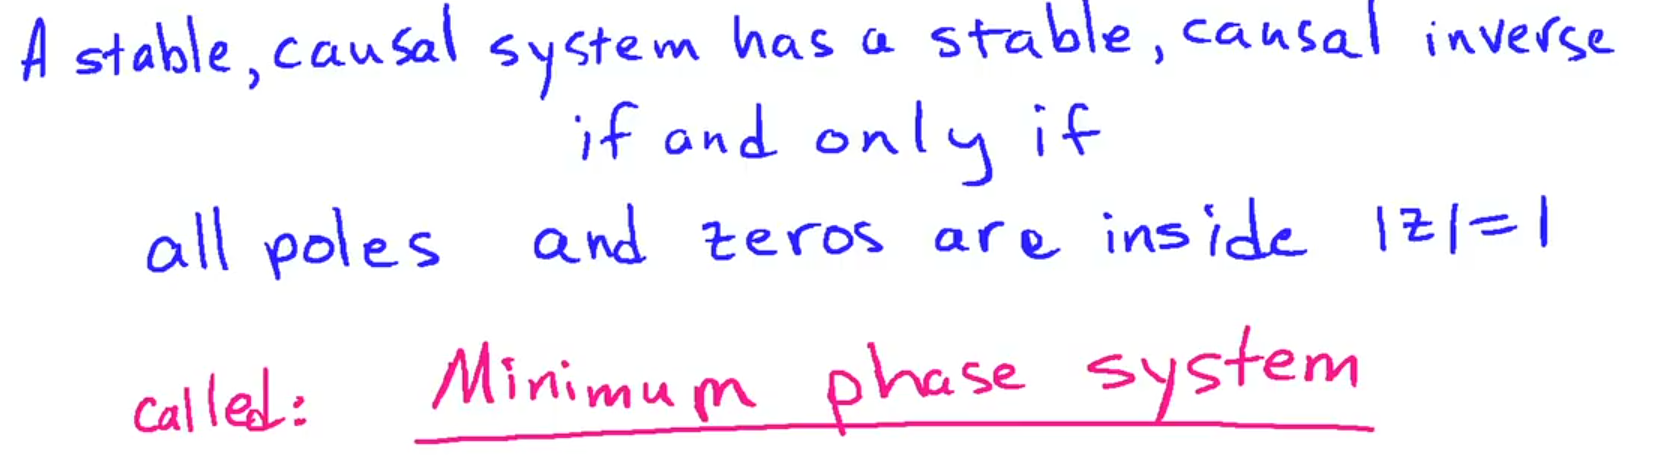

A causal and stable LTI system with a causal and stable inverse is known as a ***minimum-phase*** system 

If poles and zeros are outside the unit circle, we call it **maximum-phase**.

If some are outside and others inside the unit circle, it is known as **mixed-phase**. 

## Invertibility

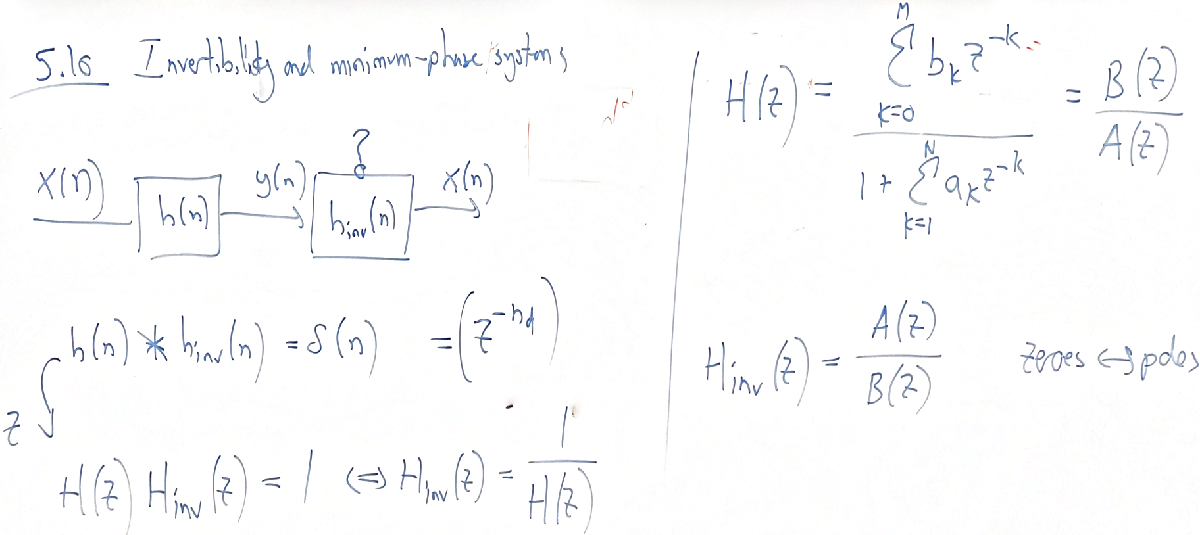

### When is a filter invertible?

A filter $H\left(z\right)=\frac{B\left(z\right)}{A\left(z\right)}$ is said to be stable and causal if all the poles of $H\left(z\right)$ are inside the unit circle.

If the inverse filter $H_{\mathrm{inv}} \left(z\right)=\frac{A\left(z\right)}{B\left(z\right)}$ has to be stable and causal, then all the poles of $H_{\textrm{inv}} \left(z\right)$ must be inside the unit circle or equivalently all zeros of $H\left(z\right)$ must be inside the unit circle.

In practice, we say that a system is only invertible if its zeros and poles are inside the unit circle.

**For a filter to be invertible, all its zeros and poles must be inside the unit circle. In other words, the filter must be minimum-phase.**

## Filter Decomposition

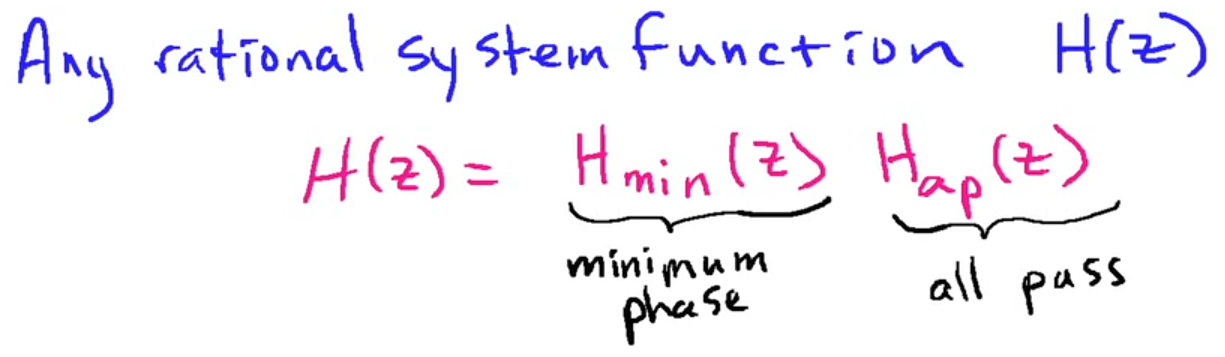

Any rationional system function can be factorised into two system functions:

        
$$H\left(z\right)=H_{\mathrm{min}} \left(z\right)\cdot H_{\mathrm{ap}} \left(z\right)$$


By decomposing $H\left(z\right)$ we made a new polynomial that consists of two parts:

- Minimum-phase system: all zeros are inside the unit circle

- All-pass system: which will have zeros outside the unit circle. We are basically storing all the phase in the all-pass filter instead

To factorise or decompose, we take following steps:

- Take the zeros of $H\left(z\right)$ that lie outside the unit circle and move them to the allpass system function $H_{\mathrm{ap}} \left(z\right)$

- Add poles to the allpass system in conjugate reciprocal locations of the zeros

- To keep the equation balanced, we add zeros in the minimum-phase system function to even out the poles  that we added to the allpass system function

Since the poles that we added to the allpass system were all inside the unit circle, the zeros that we added to the minimim-phase system are also inside the unit circle.

### Magnitude Response of Decomposition

Plotting the maginatude response of the original system and the minimum-phase system, we observe that they are on top of each other

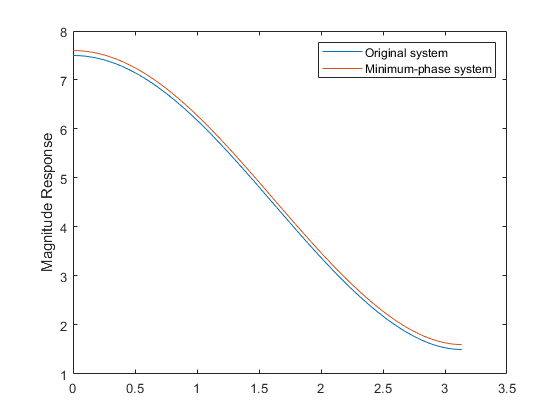

[H_orig, w] = freqz([1, 4.5, 2]); % Original
[H_min, w] = freqz([4, 3,   0.5]);
[H_ap, w] = freqz([1/4, 1], [1, 1/4]);

% Add 0.1 otherwise they will be on top of each other
plot(w, abs(H_orig), w, abs(H_min)+0.1)
legend('Original system', 'Minimum-phase system')
ylabel('Magnitude Response')

### Phase response of the Decomposition

We can plot the phase of the three systems. The phase of the original system is hidden in the all-pass system. So by decomposing a filter into minimum-phase and all-pass systems, the excess phase is stored in the all-pass system. The phase lag of a system with poles and zeros inside the unit cicle is less than the original system which had the identical magnitude response.

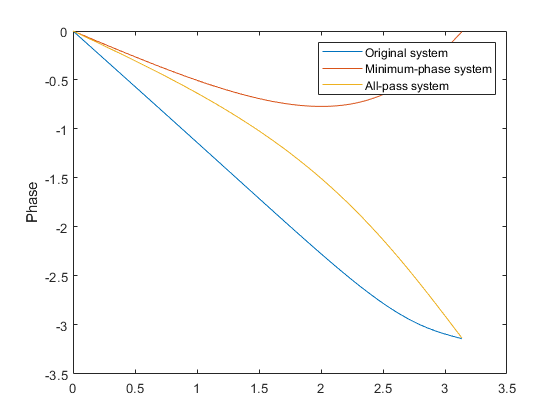

plot(w, angle(H_orig), w, angle(H_min), w, angle(H_ap))
ylabel('Phase')
legend('Original system', 'Minimum-phase system', 'All-pass system')

### Why is the decomposition useful?

This decomposition is useful if we want to find an approximate inverse system for $H\left(z\right)$.

The minimum-phase component of any system can be inverted. This allows os to take any system, run a signal $x\left(n\right)$ through it and run the output $y\left(n\right)$ through the inverse of the minimum-phase part.

The end result is the same as passing the signal $x\left(n\right)$ through an allpass filter. 

What we achieve is that:

- no magnitude distortion meaning that the magnitude of each frequency is not altered by the process

- we only get phase distortion (which may not be important depending on the application)

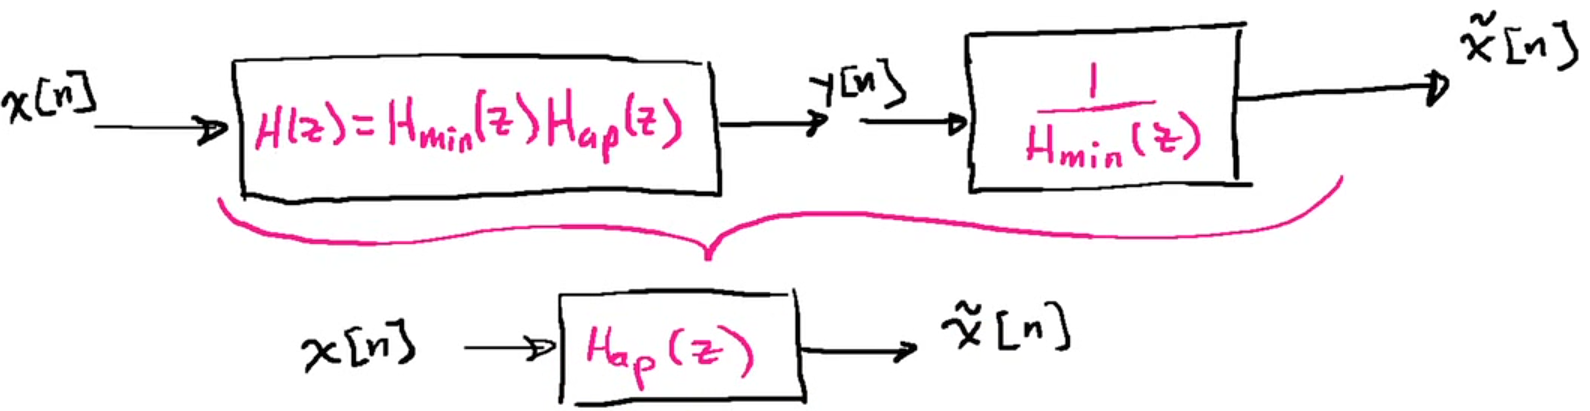

The magnitude response of an allpass filter is constant for all frequencies, however its phase response may different. For this reason, allpass filters are used for **delay equalisation**.

### Minimum Delay Property

What happens when we take a zero and flip it. We know that the magnitude response does not change.

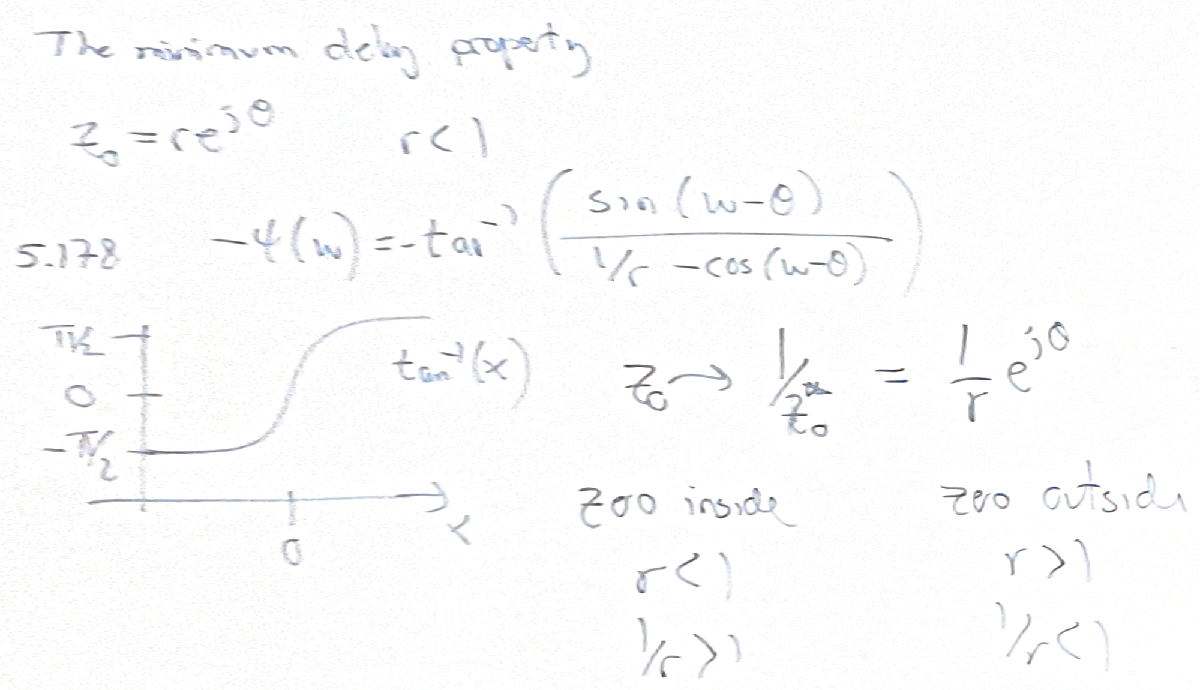

By setting $r<1$ we specifically place the zero inside the unit circle.

If we flip $z_0$ to $\frac{1}{z_0^* }=\frac{1}{r}e^{j\phi }$

If we have zero inside $r<1$ then $\frac{1}{r}>1$

If we have zero outside $r>1$ then $\frac{1}{r}<1$

The only thing that changes in the phase response when we flip $z_0$ to inside the unit circle is $\frac{1}{r}$.

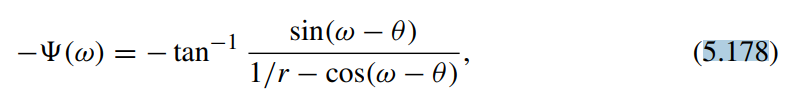

If we go from zero inside to outside, the $\frac{1}{r}$ becomes smaller. The tangent will increase and we get a larger number. This means that we get more phase. So we add phase as the zero goes from inside the unit circle to outside the unit circle. 

If we look at the group delay:

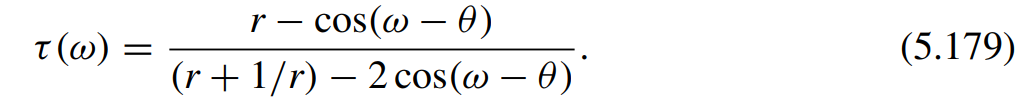

By taking a zero that is inside the unit circle and putting it outside, we increase the group delay.

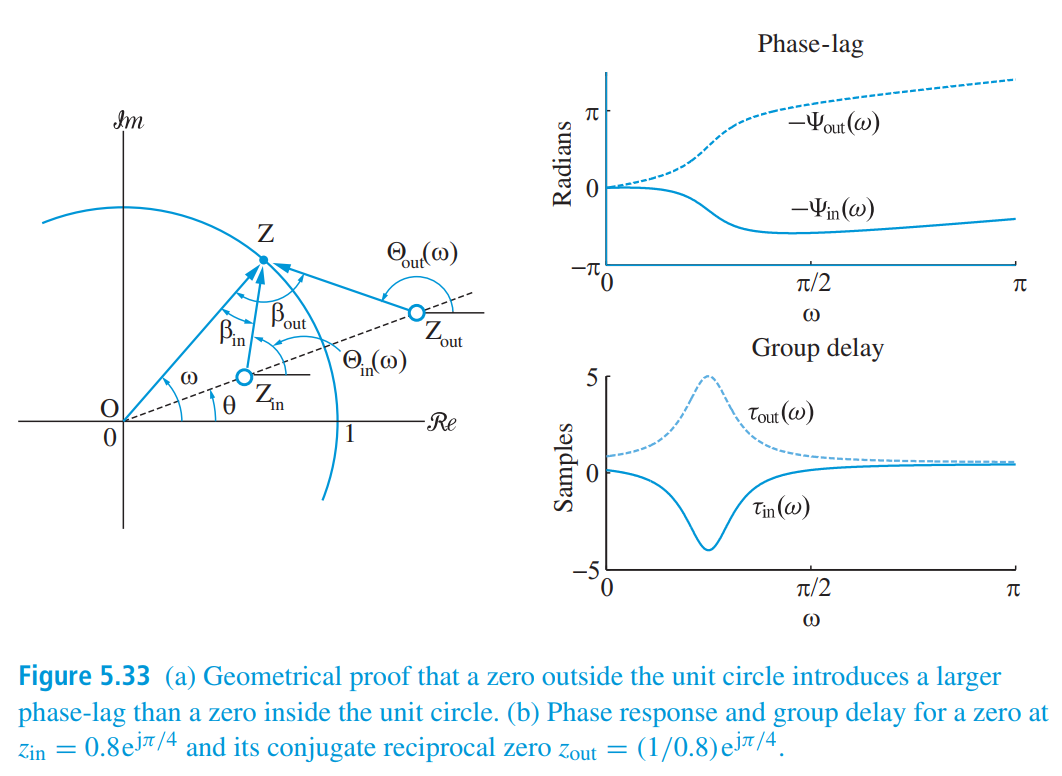

## Exam 2015 Problem 4: True/False

### A serial connection of two all-pass filters is also an all-pass filter.

Answer: TRUE

The transfer function of a serial connection of two fiters is just the individual transfer functions multiplied. For the magnitude part this becomes:

        

### Is a system invertible?

clear variables;

Answer: FALSE!

A filter $H\left(z\right)=\frac{B\left(z\right)}{A\left(z\right)}$ is said to be stable and causal if all the poles of $H\left(z\right)$ are inside the unit circle.

If the inverse filter $H_{\mathrm{inv}} \left(z\right)=\frac{A\left(z\right)}{B\left(z\right)}$ has to be stable and causal, then all the poles of $H_{\textrm{inv}} \left(z\right)$ must be inside the unit circle or equivalently all zeros of $H\left(z\right)$ must be inside the unit circle.

In practice, we say that a system is only invertible if its zeros and poles are inside the unit circle (minimum phase).

Plotting the poles and zeros of the given system function, we observe that the zero is outside the unit circle.

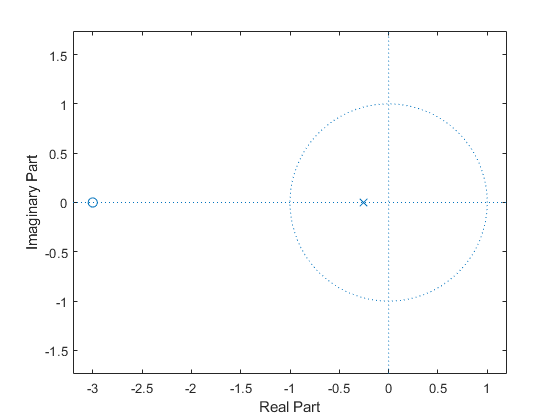

b = [1, 3];
a = [1, 1/4];
zplane(b, a)

### Is a filter invertible if the poles of the system function lies within the unit circle?

Answer: FALSE.

A filter $H\left(z\right)=\frac{B\left(z\right)}{A\left(z\right)}$ is said to be stable and causal if all the poles of $H\left(z\right)$ are inside the unit circle.

If the inverse filter $H_{\mathrm{inv}} \left(z\right)=\frac{A\left(z\right)}{B\left(z\right)}$ has to be stable and causal, then all the poles of $H_{\textrm{inv}} \left(z\right)$ must be inside the unit circle or equivalently all zeros of $H\left(z\right)$ must be inside the unit circle.

So if we want the inverse filter to be stable, then the answer is false. Typically, we want an inversable filter to be minimum-phase which means that the filter *and* its inverse must causal and stable.

For a filter to be invertible, zeros and poles must be inside the unit circle.

### Quiz: can a system with zeros located exactly on the unit circle be inverted?

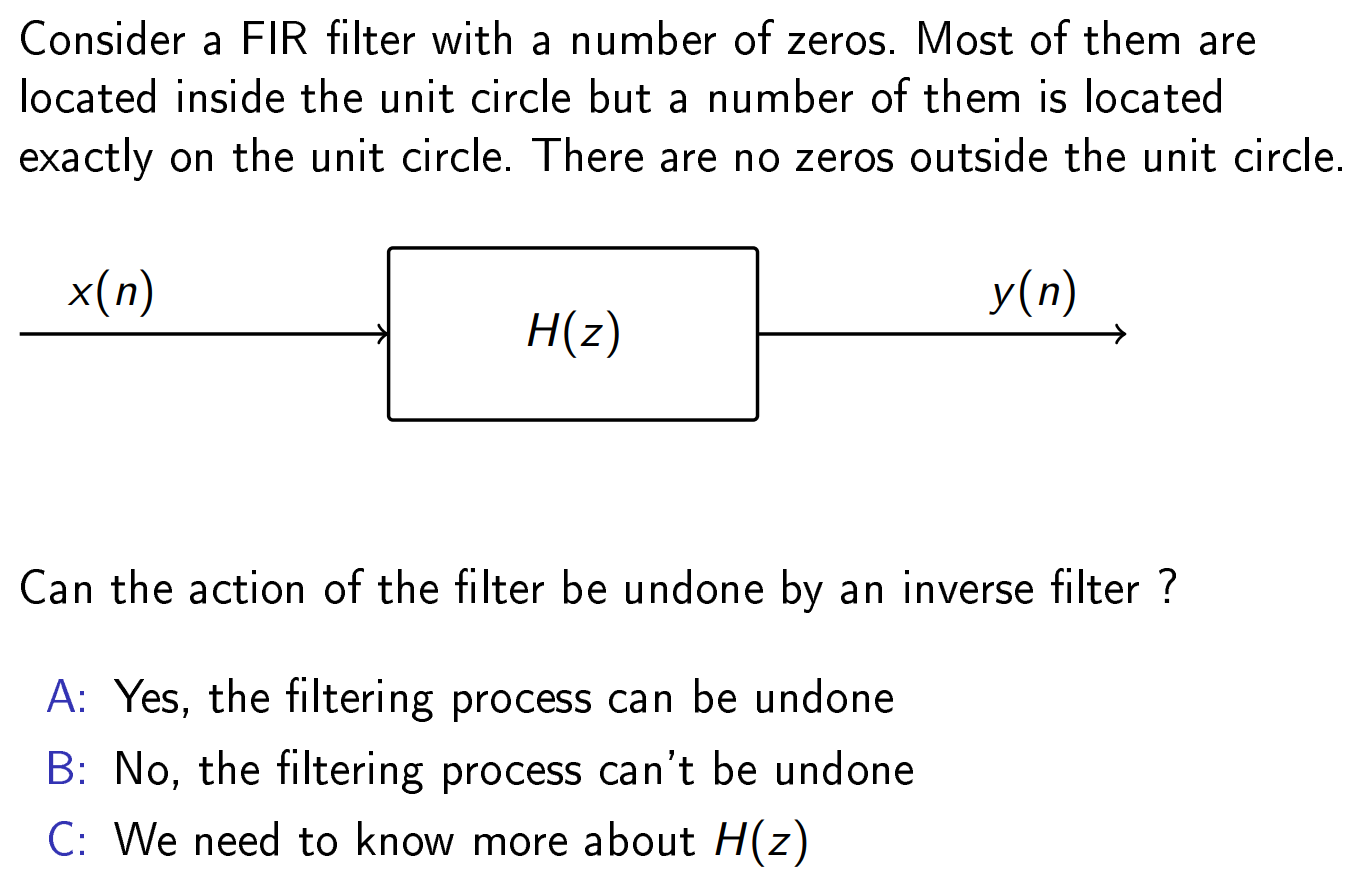

The answer is NO. If we have a FIR where the zero is exactly at 1 kHz. Given a signal, the filter will remove frequency component at 1 kHz. The problem is that the inverse filter cannot reconstruct the original signal because we have deleted information from the signal i.e., the missing frequency component cannot be recovered.

### Quiz: Determine a minimum-phase filter based on impulse response

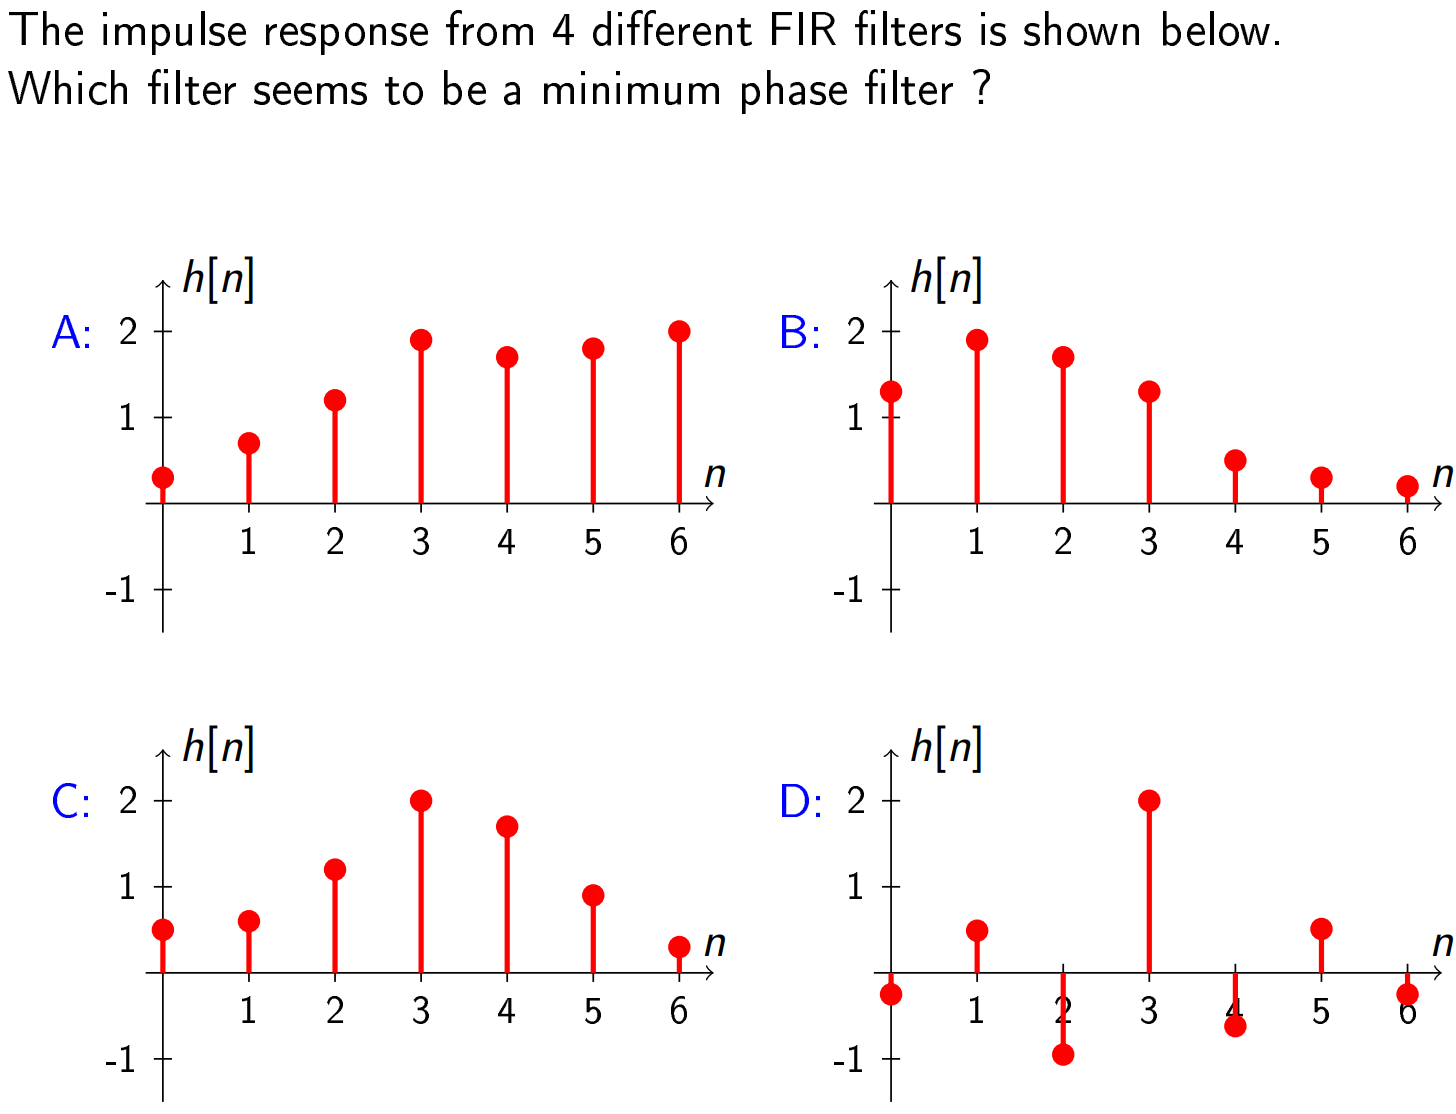

The answer is B. Minimum-phase is the same thing as minimum group delay. If we put in energy any of these four filters, which one is the fastest to respond and pass the signal though. How fast does the system propagate the energy of a signal through the filter? If it is slow, then it is maximum-phase. If a filter is in-between then it is mixed-phase. If it is very phase, then it is minimum-phase.

A and D has all the energy at the late end so it takes a while before all the energy passes through the system. Therefore, they has larger group delay than B, where the larger impulses are early. 

Comparing B and C: B has energy at the begining, whereas C the energy is in the middle. 

- A: Maximum-phase

- B: Minimum-phase

- C: Mixed-phase

- D: Mixed-hase

Let us simulate filter D in MATLAB:

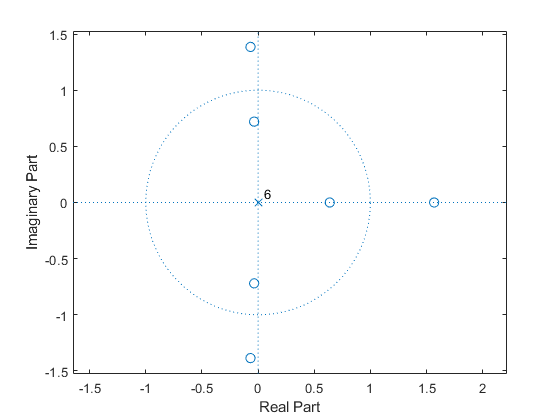

zplane([-1, 2, -3, 5, -3, 2, -1])

### Quiz: Has a linear phase filter a mixed group delay?

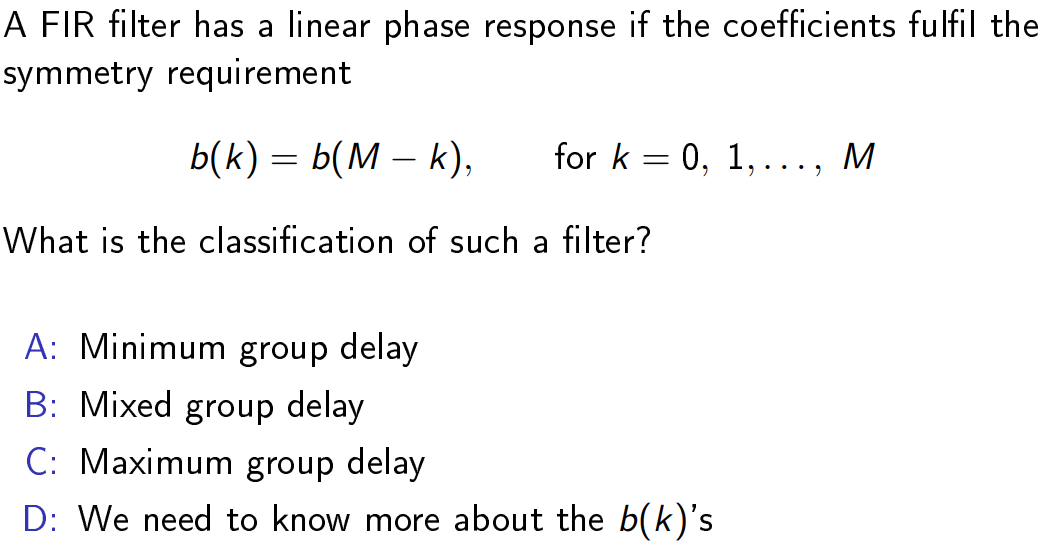

Recall that linear phase correspond to unity group delay. 

The symmetry will be in the middle of the filter. The answer is B.

We can try it out in MATLAB. If we plot the a linear phase filter, we get two zeros inside and two zeros outside. Thefore, the filter is mixed-phase filter.

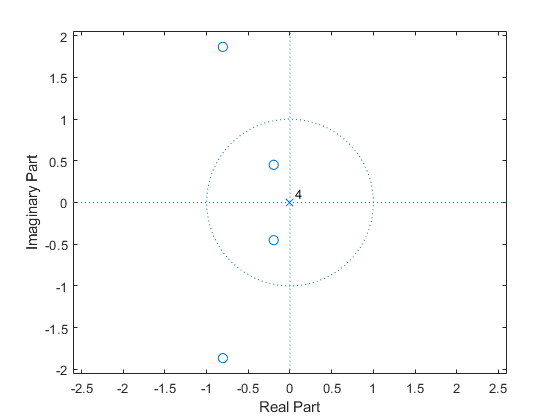

zplane([1, 2, 5, 2, 1])

The reason why the filter is called linear phase filter:

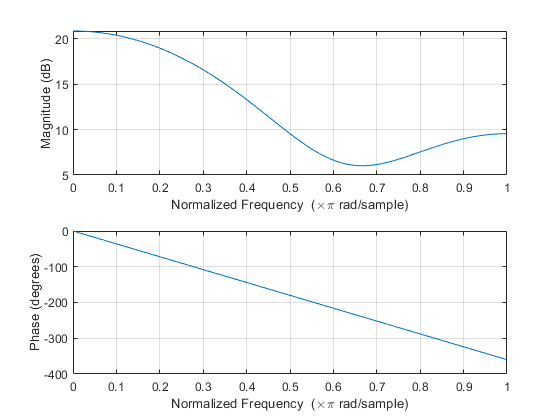

freqz([1, 2, 5, 2, 1])

### Problem: Decompose a filter into minimum-phase and allpass

  Decompose the system $H\left(z\right)=H_1 \left(z\right)\left(1-\beta z^{-1} \right)$ where $|\beta |>1$ and $H_1 \left(z\right)$ is a minimum-phase system

To factorise or decompose, we take following steps:

- Take the zeros of $H\left(z\right)$ that lie outside the unit circle and move them to the allpass system function $H_{\mathrm{ap}} \left(z\right)$

- Add poles to the allpass system in conjugate reciprocal locations of the zeros

- To keep the equation balanced, we add zeros in the minimum-phase system function to even out the poles  that we added to the allpass system function

Since the poles that we added to the allpass system were all inside the unit circle, the zeros that we added to the minimim-phase system are also inside the unit circle.

**Step 1:** We notice that $1-\beta z^{-1}$ is not an allpass system. We want it to look like this:

        

So we start by factorising $-\beta$ out. By doing this, we put a zero into allpass system

        
$$H\left(z\right)=H_1 \left(z\right)\left(-\beta \right)\left(-\frac{1}{\beta }+z^{-1} \right)=H_1 \left(z\right)\left(-\beta \right)\left(z^{-1} -\frac{1}{\beta }\right)$$


**Step 2:** We need to put a pole into the allpass system that is in conjugate reciprocal locations of the zero

        
$$H\left(z\right)=H_1 \left(z\right)\left(-\beta \right)\left(\frac{z^{-1} -\frac{1}{\beta }}{1-\frac{1}{\beta^* }z^{-1} }\right)$$


**Step 3:** To keep the equality, we have to introduce a zero to the minimum-phase system function 

        
$$H\left(z\right)=H_1 \left(z\right)\left(-\beta \right)\left(1-\frac{1}{\beta^* }z^{-1} \right)\left(\frac{z^{-1} -\frac{1}{\beta }}{1-\frac{1}{\beta^* }z^{-1} }\right)$$


Now the decomposition is:

        
$$H\left(z\right)=H_{\mathrm{min}} \left(z\right)H_{\mathrm{ap}} \left(z\right)$$


where:

        
$$H_{\mathrm{min}} \left(z\right)=H_1 \left(z\right)\left(-\beta \right)\left(1-\frac{1}{\beta^* }z^{-1} \right)$$


        
$$H_{\mathrm{ap}} \left(z\right)=\frac{z^{-1} -\frac{1}{\beta }}{1-\frac{1}{\beta^* }z^{-1} }$$


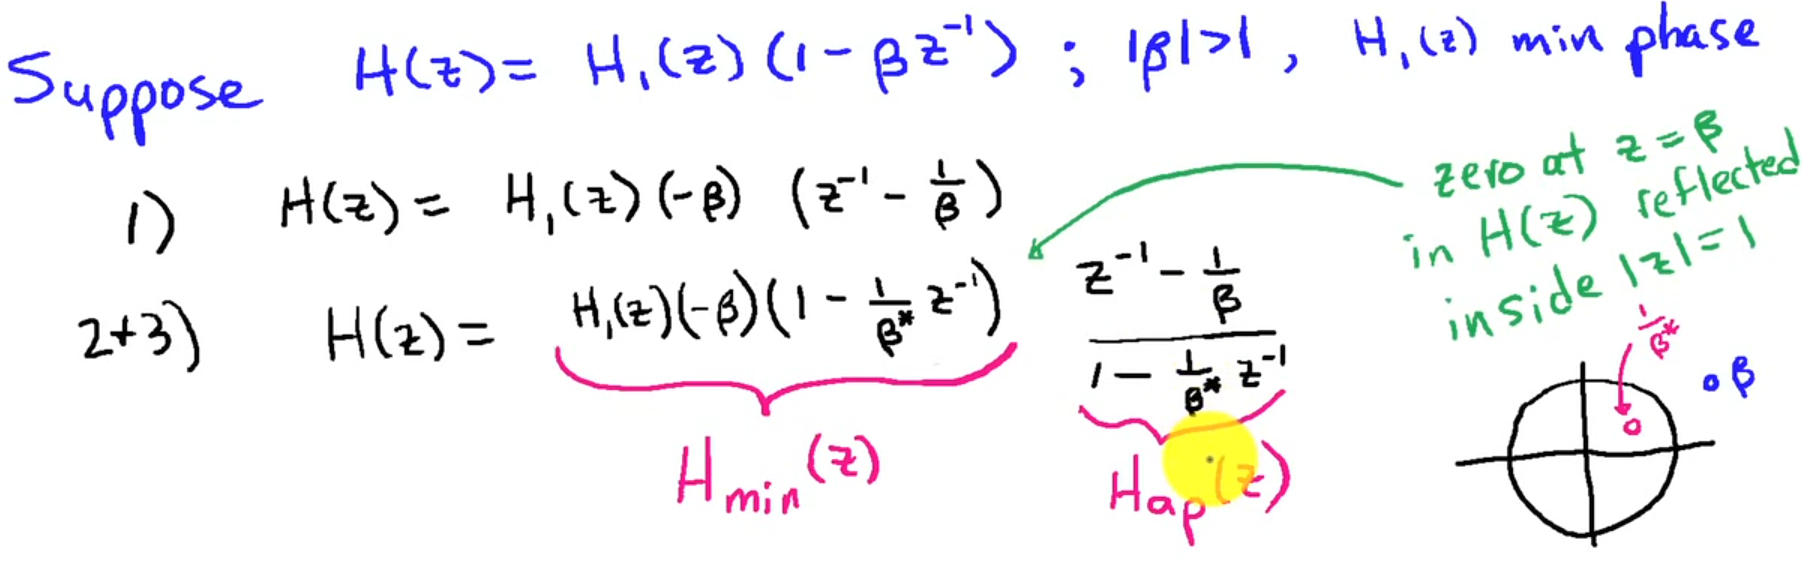

### Problem: Decompose a filter into minimum-phase and allpass

  Decompose the system $H\left(z\right)=1+4\ldotp 5z^{-1} +2z^{-2}$

To factorise or decompose, we take following steps:

- Take the zeros of $H\left(z\right)$ that lie outside the unit circle and move them to the allpass system function $H_{\mathrm{ap}} \left(z\right)$

- Add poles to the allpass system in conjugate reciprocal locations of the zeros

- To keep the equation balanced, we add zeros in the minimum-phase system function to even out the poles  that we added to the allpass system function

Since the poles that we added to the allpass system were all inside the unit circle, the zeros that we added to the minimim-phase system are also inside the unit circle.

**Step 1:** Take the zeros of $H\left(z\right)$ that lie outside the unit circle and move them to the allpass system function

First, we need to write it as a product of two system functions. We can do that by finding the zeros:

roots([1, 4.5, 2])

Now we can write the system as:

        
$$H\left(z\right)=\left(1-\left(-0\ldotp 5\right)z^{-1} \right)\left(\left(1-\left(-4\right)z^{-1} \right)\right)$$


        
$$H\left(z\right)=\left(1+0\ldotp 5z^{-1} \right)\left(1+4z^{-1} \right)$$


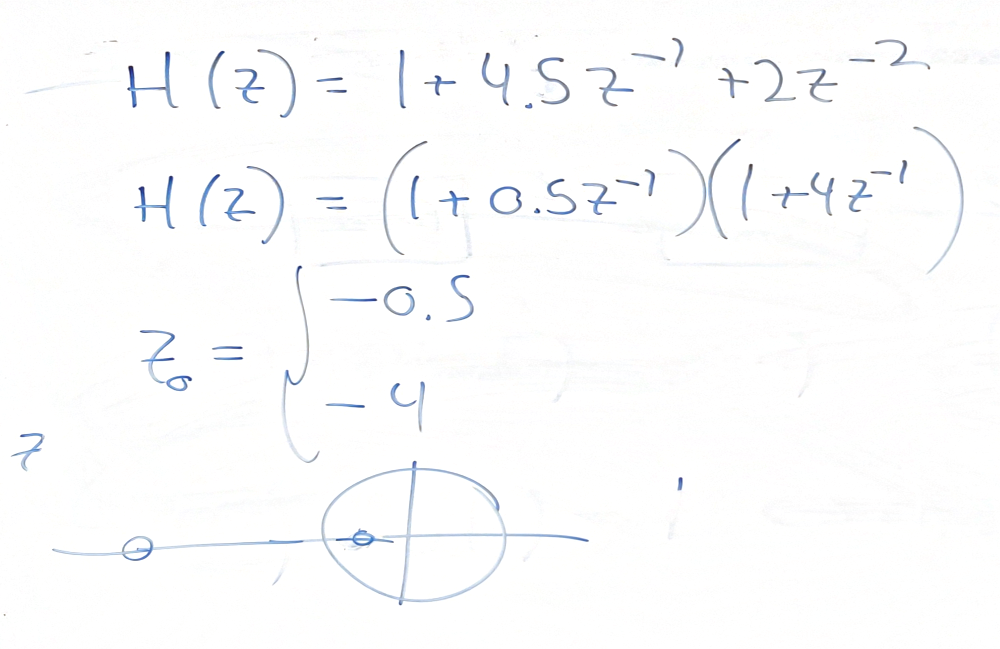

One zero $z=-0\ldotp 5$ is inside the unit circle and the other is outside $z=-4$. We want to flip the zero outside the unit circle to be inside the unit circle.

So we start by factorising $4$ out. By doing this, we put a zero into allpass system.

        
$$H\left(z\right)=\left(1+0\ldotp 5z^{-1} \right)\left(4\right)\left(\frac{1}{4}+z^{-1} \right)=4\left(1+0\ldotp 5z^{-1} \right)\left(z^{-1} +\frac{1}{4}\right)$$


**Step 2:** We need to put a pole into the allpass system that is in conjugate reciprocal locations of the zero

        
$$H\left(z\right)=4\left(1+0\ldotp 5z^{-1} \right)\left(\frac{z^{-1} +\frac{1}{4}}{1+\frac{1}{4}z^{-1} }\right)$$


**Step 3:** To keep the equality, we have to introduce a zero to the minimum-phase system function 

        
$$H\left(z\right)=4\left(1+0\ldotp 5z^{-1} \right)\left(1+\frac{1}{4}z^{-1} \right)\left(\frac{z^{-1} +\frac{1}{4}}{1+\frac{1}{4}z^{-1} }\right)$$


To tidy up, we will multiply the first three products together.Multiplying two polynomials together is the same as doing convolution:

4 * conv([1, 0.5], [1, 1/4])

So we can rewrite the system function as:

        
$$H\left(z\right)=\left(4+3z^{-1} +0\ldotp 5z^{-2} \right)\left(\frac{z^{-1} +\frac{1}{4}}{1+\frac{1}{4}z^{-1} }\right)$$


## ADSI Problem 1.2

### 1) Compute the impulse response of allpass filter

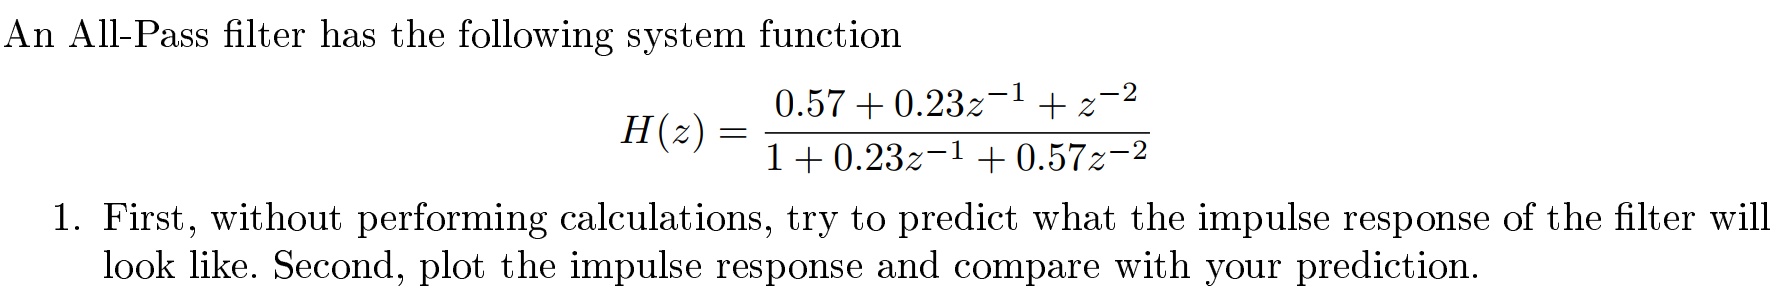

b = [0.57, 0.23, 1];

$$H\_min = \frac{3}{z}-\frac{2}{z^{2}}+\frac{1}{2\,z^{3}}-2$$

$$H\_ap = -\frac{\frac{1}{z}-\frac{1}{2}}{\frac{1}{2\,z}-1}$$

a = [1, 0.23, 0.57];
impz(b, a);

### 2) Quantisation errors

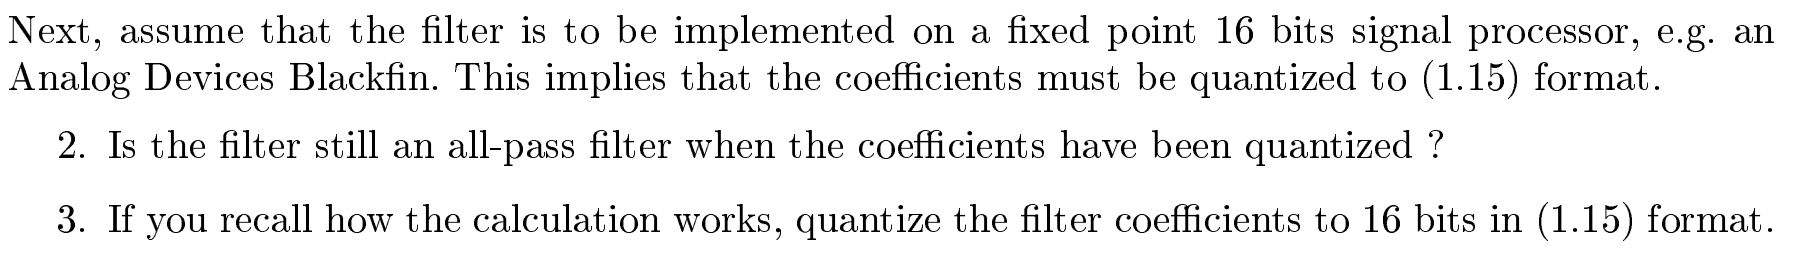

b = [0.57, 0.23, 1];
a = [1, 0.23, 0.57];
[h, t] = impz(b, a);

bits = 16;
maxVal = (2^(bits-1))-1;
minVal = (2^(bits-1));


Normalise the inpulse response between -1 and +1 assuming that the maximum value is positive.

normalisedH = h./max(h);

Quantise the positive values 

quantisedH = normalisedH.* maxVal;

Find the index of negative values:

negIndices = find(normalisedH < 0);
quantisedH(negIndices) = normalisedH(negIndices).* minVal;


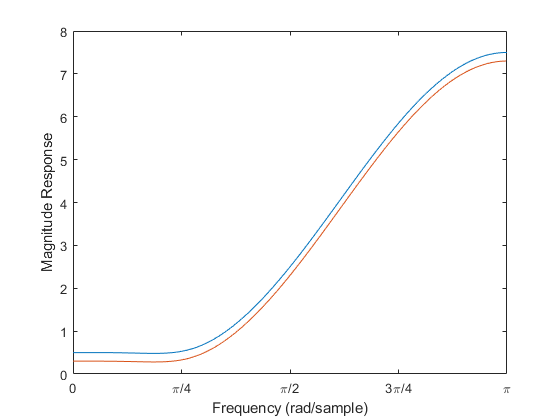

stem([0:34], h);
title('Floating-Point impulse response');

stem([0:34], quantisedH);
title('Fixed-point impulse response');

## ADSI Problem 1.4: Filter decomposition

clear variables;

### 1) Decompose a FIR filter with one zero outside the unit circle

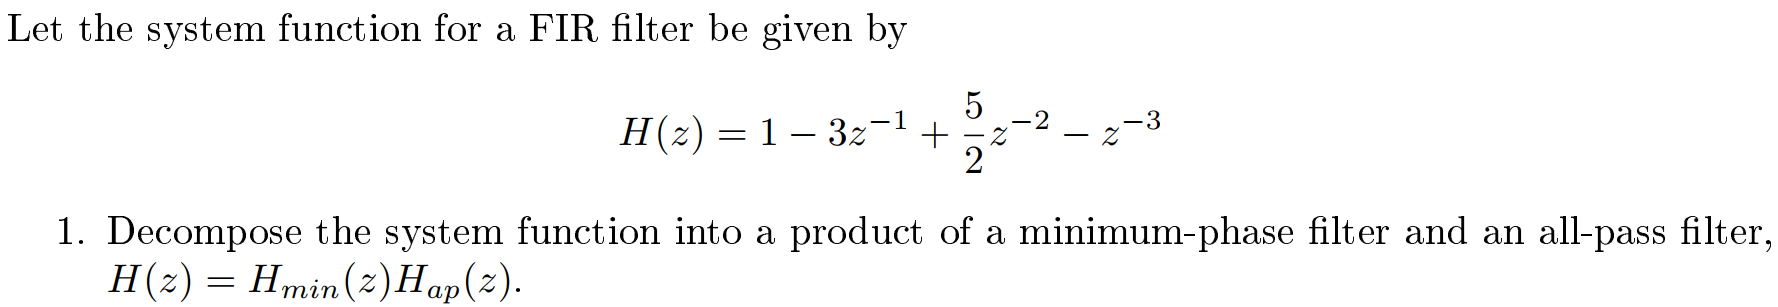

To decompose the system function, we take following steps:

- Take the zeros of $H\left(z\right)$ that lie outside the unit circle and move them to the allpass system function $H_{\mathrm{ap}} \left(z\right)$

- Add poles to the allpass system in conjugate reciprocal locations of the zeros

- To keep the equation balanced, we add zeros in the minimum-phase system function. This will even out the poles  that we added to the allpass system function.

Since the poles that we added to the allpass system were all inside the unit circle, the zeros that we added to the minimim-phase system are also inside the unit circle.

This is coded in a MATLAB function:

h = [1, -3, 5/2, -1];
[H_min, H_ap] = decompose_min_ap(h)

We put everything together:

        
$$H\left(z\right)=H_{\mathrm{min}} \left(z\right)H_{\mathrm{ap}} \left(z\right)$$


                 
$$=\left(-2+3z^{-1} -2z^{-2} +\frac{1}{2}z^{-3} \right)\left(\frac{z^{-1} -0\ldotp 5}{1-0\ldotp 5z^{-1} }\right)$$


### 2) Show that the system and its correspond minimum-phase have the same magnitude response

To show that $H\left(z\right)$ and $H_{\mathrm{min}} \left(z\right)$ have the same magnitude response, we can plot them. If the two graphs are on top of each other then then they have the same magnitude response.

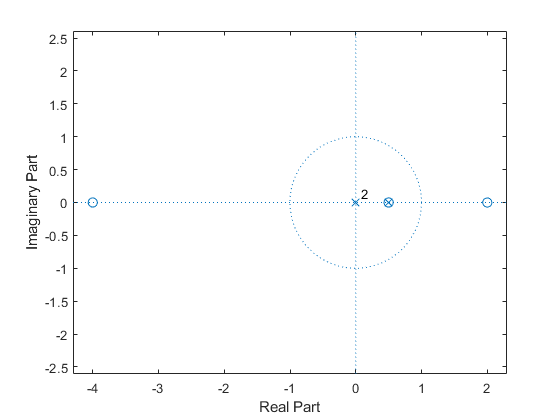

% Coefficients for H(z)

b = [1, -3, 5/2, -1];

$$H\_min = \frac{10}{z}-\frac{3}{z^{2}}-\frac{1}{2\,z^{3}}+\frac{1}{4\,z^{4}}-8$$

$$H\_ap = -\frac{\left(\frac{1}{z}-\frac{1}{2}\right)\,\left(\frac{1}{z}+\frac{1}{4}\right)}{\left(\frac{1}{2\,z}-1\right)\,\left(\frac{1}{4\,z}+1\right)}$$

a = 1;
[H, w] = freqz(b,a,'whole');

% Coefficients for H_min(z)

$$H\_ap\_num = \frac{1}{4\,z}-\frac{1}{z^{2}}+\frac{1}{8}$$

H_min_b = [-2, 3, -2, 1/2];

$$H\_ap\_den = \frac{1}{4\,z}+\frac{1}{8\,z^{2}}-1$$

H_min_a = 1;
[H_min_z, H_min_w] = freqz(H_min_b, H_min_a);

$$ans = \frac{\frac{2}{z}-\frac{8}{z^{2}}+1}{\frac{2}{z}+\frac{1}{z^{2}}-8}$$

% plot(H_min_w, log10(abs(H_min_z)));

% The offset ensures that the two graphs are not on top of each other
offset = -0.2;
plot(w, abs(H), H_min_w, abs(H_min_z) + offset); 
set(gca,'XTick',0:pi/4:pi)
set(gca,'XTickLabel',{'0','\pi/4','\pi/2','3\pi/4','\pi'})
xlabel('Frequency (rad/sample)')
ylabel('Magnitude Response')
xlim([0, pi]);

### 3) Decompose a filter that has two zeros outside the unit circle

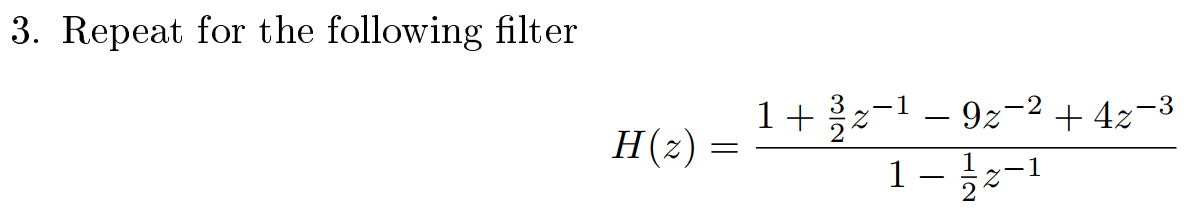

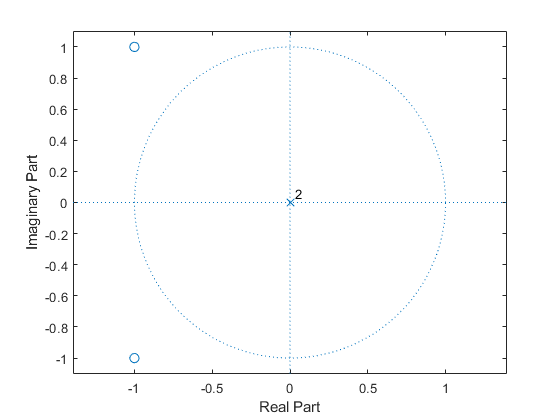

b = [1, 3/2, -9, 4];

a = [1, -1/2];

Plot the zeros and the poles:

zplane(b, a);
[H_min, H_ap] = decompose_min_ap(b)

$$H\_min = \frac{2}{z}+\frac{1}{z^{2}}+2$$

$$H\_ap = \frac{\left(\frac{1}{z}+\frac{1}{2}-\frac{1}{2}\,\mathrm{i}\right)\,\left(\frac{1}{z}+\frac{1}{2}+\frac{1}{2}\,\mathrm{i}\right)}{\left(1+\frac{\frac{1}{2}-\frac{1}{2}\,\mathrm{i}}{z}\right)\,\left(1+\frac{\frac{1}{2}+\frac{1}{2}\,\mathrm{i}}{z}\right)}$$

Expanding the numerator, we get:

syms z;

$$H\_ap\_num = \frac{1}{z}+\frac{1}{z^{2}}+\frac{1}{2}$$

H_ap_num = expand(-1*(1/z - 1/2)*(1/z + 1/4))

$$H\_ap\_den = \frac{1}{z}+\frac{1}{2\,z^{2}}+1$$

H_ap_den = expand((1/(2*z) - 1)*(1/(4*z) + 1))

We can multiply both the numerator and denominator with 8, to get nice numbers:

(H_ap_num * 8) / (H_ap_den * 8)

Now, we can write the transfer function for the allpass filter:

        
$$H_{\mathrm{ap}} \left(z\right)=\frac{1+2z^{-1} -8z^{-2} }{-8+2z^{-1} +z^{-2} }$$


So we have:

        
$$H\left(z\right)=H_{\mathrm{min}} \left(z\right)H_{\mathrm{ap}} \left(z\right)$$


                
$$=\left(-8+2z^{-1} +z^{-2} \right)\left(\frac{1+2z^{-1} -8z^{-2} }{-8+2z^{-1} +z^{-2} }\right)$$


## [✔] ADSI Problem 1.5 Filter decomposition

### 1) Show that a FIR filter with a difference equation is not minimum-phase

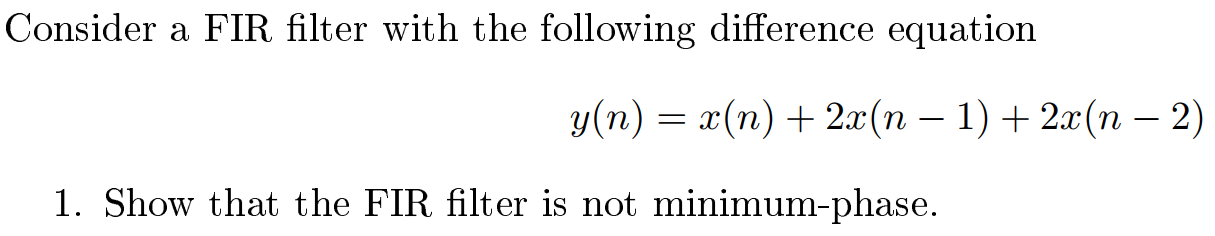

To determine whether the filter is a minimum-phase or not, we need get the transfer function of this FIR filter $H\left(z\right)$ which is defined as:

        
$$H\left(z\right)=\frac{Y\left(z\right)}{X\left(z\right)}=\frac{b_0 +b_1 z^{-1} +b_2 z^{-2} \cdots +b_M z^{-M} }{1+a_1 z^{-1} +a_2 z^{-2} \cdots +a_N z^{-N} }$$


This means that we must take the z-transform of difference equation:

        
$$\begin{array}{l}
Y\left(z\right)\;=X\left(z\right)+2X\left(z\right)z^{-1} +2X\left(z\right)z^{-2} \\
Y\left(z\right)\;=X\left(z\right)\left(1+2z^{-1} +2z^{-2} \right)\\
\frac{Y\left(z\right)}{X\left(z\right)}=1+2z^{-1} +2z^{-2} \\
H\left(z\right)=1+2z^{-1} +2z^{-2} 
\end{array}$$


Once we have the transfer function, we can determine if the filter is a minimum-phase by looking at the zplane plot:

zplane([1, 2, 2])

Since all the zeros are outside the unit cirlce, clearly the given FIR filter is not minimum-phase. It is a **maximum-phase**.

### 2) Find the difference equation for the corresponding minimum-phase FIR filter

To decompose the system function, we take following steps:

- Take the zeros of $H\left(z\right)$ that lie outside the unit circle and move them to the allpass system function $H_{\mathrm{ap}} \left(z\right)$

- Add poles to the allpass system in conjugate reciprocal locations of the zeros

- To keep the equation balanced, we add zeros in the minimum-phase system function. This will even out the poles  that we added to the allpass system function.

Since the poles that we added to the allpass system were all inside the unit circle, the zeros that we added to the minimim-phase system are also inside the unit circle.

This is coded in a MATLAB function.

We found that the transfer function for the difference equation is:

        
$$H\left(z\right)=1+2z^{-1} +2z^{-2}$$


h = [1, 2, 2];
[H_min, H_ap] = decompose_min_ap(h)

Let us simply this expression:

H_ap_num = expand((1/z + 1/2 - 1/2i) * (1/z + 1/2 + 1/2i))
H_ap_den = expand((1+ (1/2 -1/2i)*z^-1) * (1 + (1/2+1/2i)*z^-1 ))

So the allpass system function is:

        
$$H_{\mathrm{ap}} \left(z\right)=\frac{\frac{1}{2}+z^{-1} +z^{-2} }{1+z^{-1} +\frac{1}{2}z^{-2} }$$


And the decomposition is:

        
$$H\left(z\right)=H_{\mathrm{min}} \left(z\right)H_{\mathrm{ap}} \left(z\right)$$


                 
$$=\left(2+2z^{-1} +z^{-2} \right)\left(\frac{\frac{1}{2}+z^{-1} +z^{-2} }{1+z^{-1} +\frac{1}{2}z^{-2} }\right)$$


The difference equation for the minimim-phase system is:

        
$$y\left(n\right)=2x\left(n\right)+2x\left(n-1\right)+x\left(n-2\right)$$


## ADSI Problem 1.8: Designing all-pass filters

clear variables;

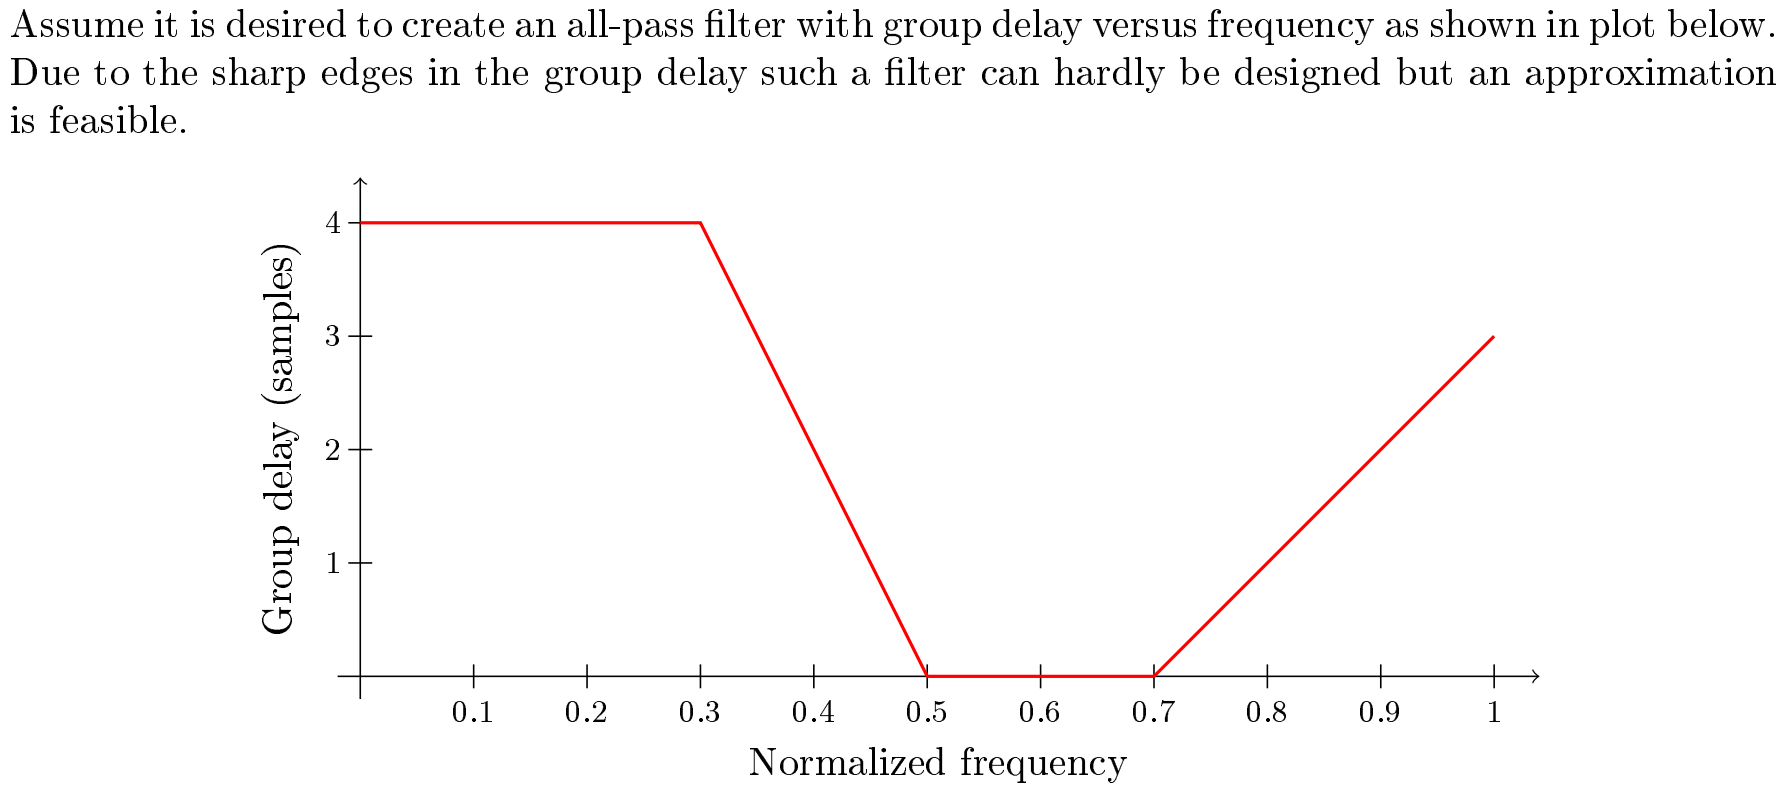

### 1) Use iirgrpdelay in MATLAB to design a 4th order all-pass filter.

You can set edges=[0 1]

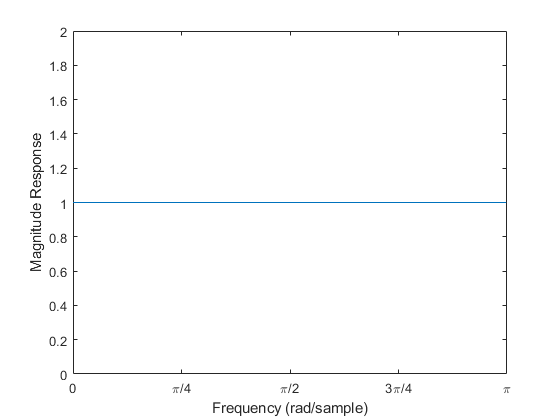

n = 4;                     % all-pass filter order
f = [0, 0.3, 0.5, 0.7, 1];
a = [4,   4,   0,   0, 3];
edges = [0, 1];

[b_ap, a_app] = iirgrpdelay(n, f, edges, a);



[H, w] = freqz(b_ap, a_app);
plot(w, H.*conj(H));
set(gca,'XTick', 0:pi/4:pi)
set(gca,'XTickLabel', {'0','\pi/4','\pi/2','3\pi/4','\pi'})
xlabel('Frequency (rad/sample)')
ylabel('Magnitude Response')
xlim([0, pi]);
ylim([0, 2])

### 2) What happens as you increase the order of the filter?

## Problem 2: Allpass filters

Let a system function be given by:

        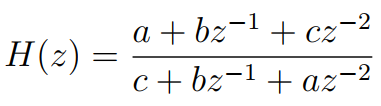

where *a*, *b *and *c *are non-zero numbers.

### 1) Show that the system function H(z) is an allpass filter

An $N$-order allpass systems is given by  

        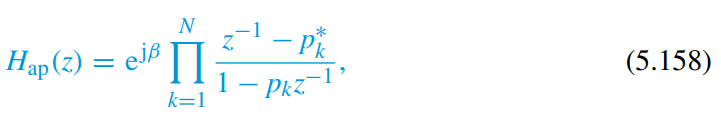  

where *β *is a constant (usually *β *= 0).

A second-order allpass system function can be expressed as:

        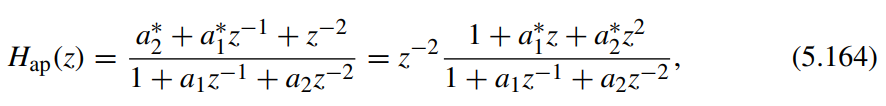

We can show that the given system function is an allpass filter if we can express it as in Eq. (5.164).

Since we want the denominator to contain a single 1 term, we scale both numerator and denominator by $\frac{1}{c}$:

        
$$H\left(z\right)=\frac{a+bz^{-1} +cz^{-2} }{c+bz^{-1} +az^{-2} }$$


        
$$H\left(z\right)=\frac{\frac{1}{c}\left(a+bz^{-1} +cz^{-2} \right)}{\frac{1}{c}\left(c+bz^{-1} +az^{-2} \right)}$$


        
$$H\left(z\right)=\frac{\frac{a}{c}+\frac{b}{c}z^{-1} +\frac{c}{c}z^{-2} }{\frac{c}{c}+\frac{b}{c}z^{-1} +\frac{a}{c}z^{-2} }$$


        
$$H\left(z\right)=\frac{\frac{a}{c}+\frac{b}{c}z^{-1} +z^{-2} }{1+\frac{b}{c}z^{-1} +\frac{a}{c}z^{-2} }$$


### 2) Realise an allpass filter as an all-pole lattice filter

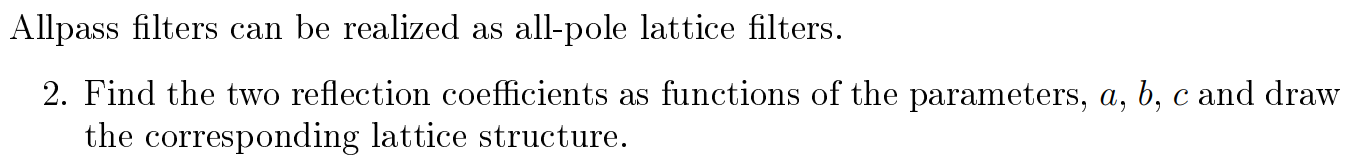

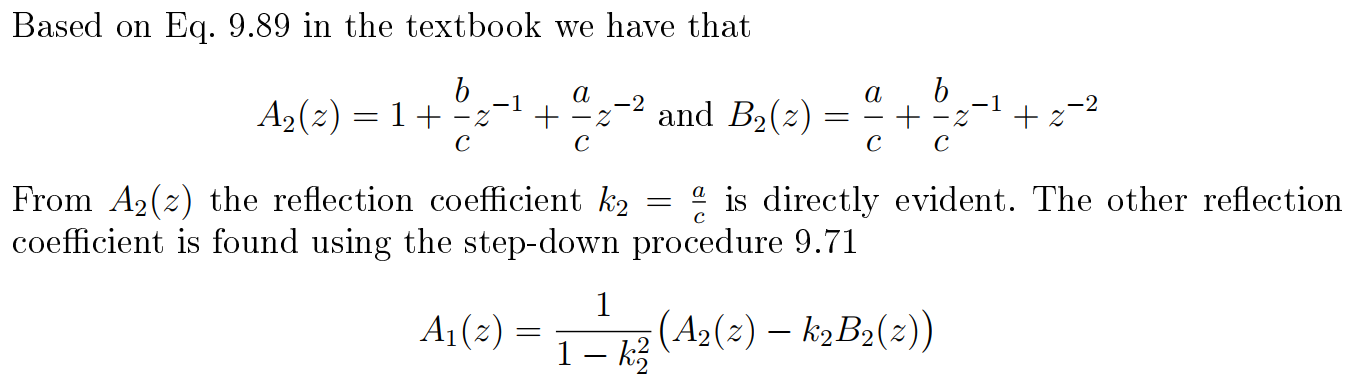

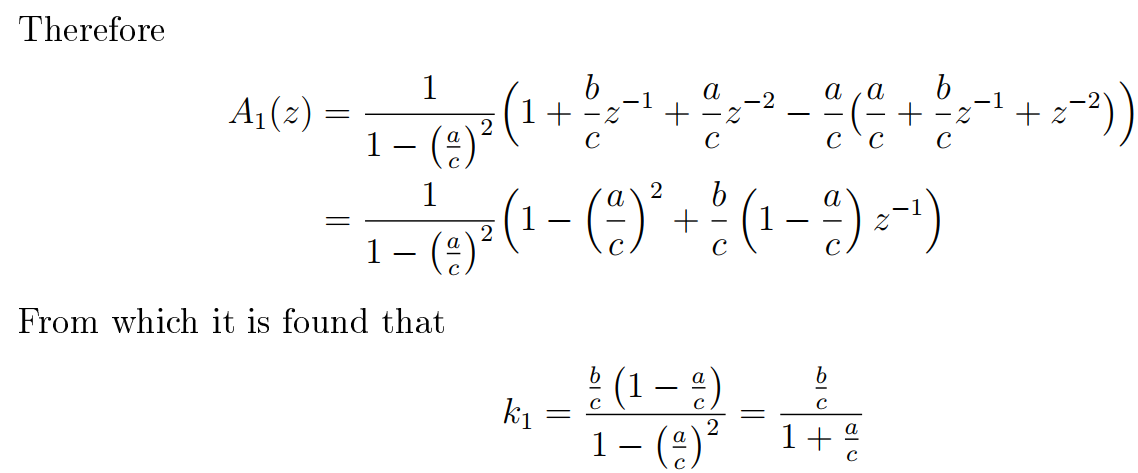

The corresponding lattice structure is

          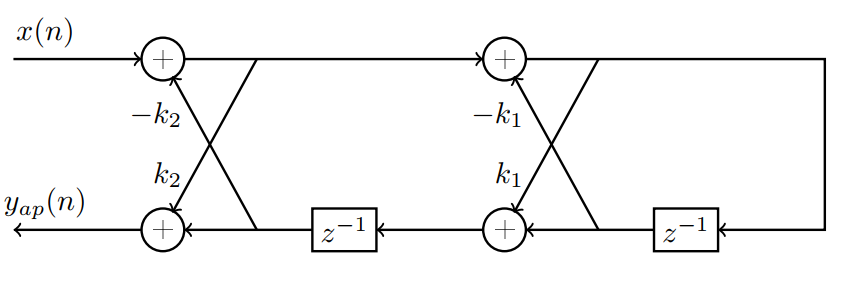

## Functions

function [H_min, H_ap]=decompose_min_ap(h)
    % Decomposes a filter into minimum-phase filter and all-pass filter
    %  h: the filter coefficients
    syms z;
    rts = roots(h);
    
    H_outside = 1; % Represents part of H where zeros are outside the unit circle
    H_inside = 1;  % Represents part of H where zeros are inside the unit circle
    zeros_outside = [];
    for i = 1:numel(rts)
        root = rts(i);
        if abs(root) > 1
            H_outside = H_outside * (1 - root*z^-1);
            zeros_outside = [zeros_outside; root];
        else
            H_inside = H_inside * (1 - root*z^-1);
        end
    end

    % Sanity check
    % H = expand(H_inside * H_outside)
    
    % Compute minimum-phase filter and all-pass filter
    H_min = 1;
    N = numel(zeros_outside);
    H_ap = 1;
    for i = 1:N
        z_i = zeros_outside(i);
        a = 1/z_i;
        a_conj = conj(a);
        H_min = H_min * (-(1/a_conj) * H_inside * (1-a * z^(-1)));
        H_ap = H_ap * (z^(-1) - a_conj) / (1 - a*z^(-1));
    end
    H_min = expand(H_min);
end

